path_verts =polyshape([-2,2,0],[-2,-2,1]);
plot(path_verts);
verts = [[-2,2,0];[-2,-2,1]]';
line_int(verts,@(x,y) -y/2, @(x,y) x/2)
line_int(verts,@(x,y) -y/2, @(x,y) x/2)


area(path_verts)

quad_vertex = [10 10; 20 10; 20 20; 10 20];
plot(polyshape(quad_vertex(:,1),quad_vertex(:,2)))
line_int(quad_vertex,@(x,y) -0.5*y.^2, @(x,y) 0*x)
centroid(polyshape(quad_vertex(:,1),quad_vertex(:,2)))

polyg = bots(3).verts_unc;
polg = polyshape(polyg(1,:),polyg(2,:));
plot(polg)
centroid(polg)
line_int(polyg,@(x,y) 0*x, @(x,y) 0.5.*x.^2)/line_int(polyg,@(x,y) 0*x, @(x,y) x)

poly2ccw(polyg(1,:),polyg(2,:))

x = sym('x');
y = sym('y');
cov = sym('c',[2,2]);
cov = [1,0;0,1];
pro_g = matlabFunction(sym((1-exp(-1/2*[x;y]'*inv(cov)*[x;y]))));
fsurf(pro_g,[-2 2 -2 2])

dist_rev=sym((1-exp(-1/2*[x;y]'*inv(cov)*[x;y])))
f_mass = int(dist_rev,x)
f_cent=int(x*dist_rev,x)
line_int(polyg,@(x,y) 0*x,matlabFunction(f_cent))/line_int(polyg,@(x,y) 0*x, matlabFunction(f_mass))

fsurf(matlabFunction(dist_rev*(-sym(pro_g)+1)),[-2 2 -2 2])

a=[0,2,0];
b = [1,2,3];
c = polyshape(a,b);
plot(c)
plot(polyshape(bots(1).obst(1,:),bots(1).obst(2,:)))

figure 
hold on
plot(bots(3).obst(1,:),bots(3).obst(2,:))
plot(bots(3).verts(1,:),bots(3).verts(2,:))


a = intersect(polyshape(bots(3).verts(1,:),bots(3).verts(2,:)),polyshape(bots(3).obst(1,:),bots(3).obst(2,:)))


syms x y
rs = 2.0;
pos = 0.0;
fun = matlabFunction(1-exp(-1/2*(pos - [x;y])'*inv([rs/2 0;0 rs/2])*(pos - [x;y])));
fsurf(fun,[-rs rs -rs rs])

a = bots(1).verts_unc - bots(1).pos;

polyrr = polyshape(a(1,:),a(2,:));
hold on
plot([a(1,:),a(1,1)],[a(2,:),a(2,1)])
plot(0,0,'d')
hold off

polyin = polyshape(bots(6).verts_unc(1,:), bots(6).verts_unc(2,:));
d = min(norm(bots(6).verts_unc - bots(6).pos_est))
plot(polyin)
plot(xc+rad.*cos(linspace(0,2*pi,100)),yc+rad.*sin(linspace(0,2*pi,100)))
polyout1 = 0;
hold on
plot(polyout1)
hold off

idd = 2

idd = 2

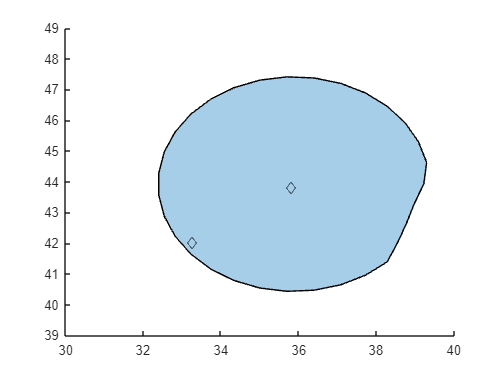

cell = polyshape(bots(idd).verts_unc(1,:), bots(idd).verts_unc(2,:));

clf
hold on
plot(cell)
plot(bots(idd).set_pt(1),bots(idd).set_pt(2),'d','color','black')
plot(bots(idd).cell_center(1),bots(idd).cell_center(2),'d','color','black')
hold off

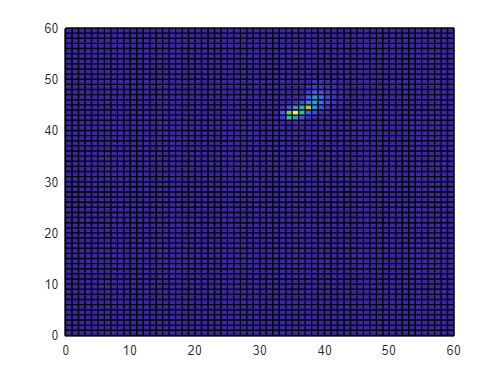

[X,Y] = meshgrid(0:bots(idd).grid_size:bots(idd).sizes+10,0:bots(idd).grid_size:bots(idd).sizes+10);
test_map = {X Y 0.1.*ones(size(X))};

indx = inpolygon(bots(idd).mesh_map{1},bots(idd).mesh_map{2},bots(idd).verts_zi(1,:),bots(idd).verts_zi(2,:));
surf(bots(idd).mesh_map{1}, bots(idd).mesh_map{2}, bots(idd).mesh_map{3}, bots(idd).mesh_map{3})

% test_map{3}(indx) = test_map{3}(indx) + bots(6).ki.*exp(-norm([test_map{1}(indx),test_map{2}(indx)]' - bots(6).set_pt)./bots(6).rho_i);
% surf(test_map{1}, test_map{2}, test_map{3}, test_map{3})
[test_map{1}(indx),test_map{2}(indx)]'- bots(idd).set_pt

ans =    -0.2600   -0.2600   -0.2600   -0.2600    0.7400    0.7400    0.7400    0.7400    0.7400    0.7400    1.7400    1.7400    1.7400    1.7400    1.7400    1.7400    1.7400    2.7400    2.7400    2.7400    2.7400    2.7400    2.7400    2.7400    3.7400    3.7400    3.7400    3.7400    3.7400    3.7400    3.7400    4.7400    4.7400    4.7400    4.7400    4.7400    5.7400    5.7400
   -0.0110    0.9890    1.9890    2.9890   -1.0110   -0.0110    0.9890    1.9890    2.9890    3.9890   -1.0110   -0.0110    0.9890    1.9890    2.9890    3.9890    4.9890   -1.0110   -0.0110    0.9890    1.9890    2.9890    3.9890    4.9890   -1.0110   -0.0110    0.9890    1.9890    2.9890    3.9890    4.9890   -0.0110    0.9890    1.9890    2.9890    3.9890    1.9890    2.9890
